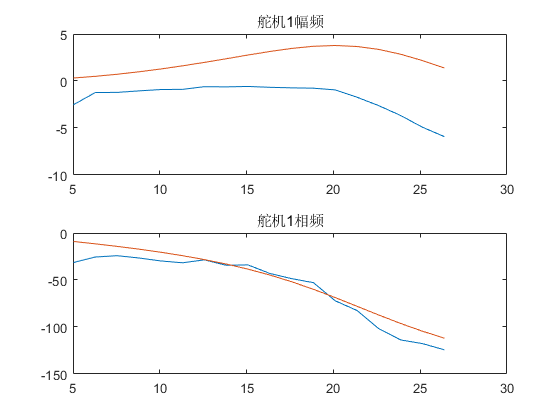

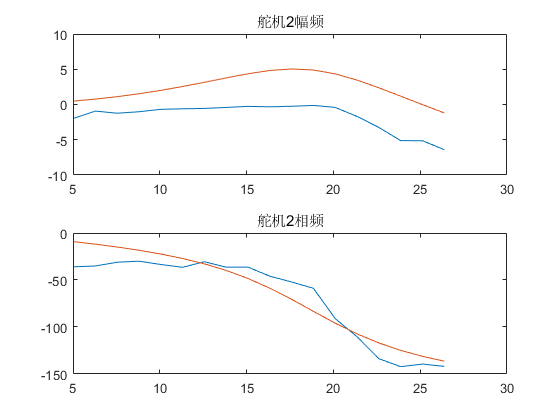

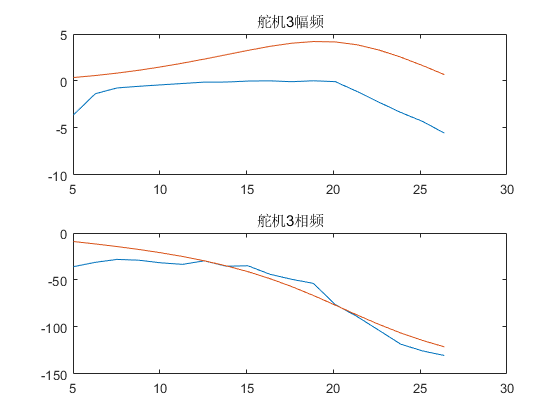

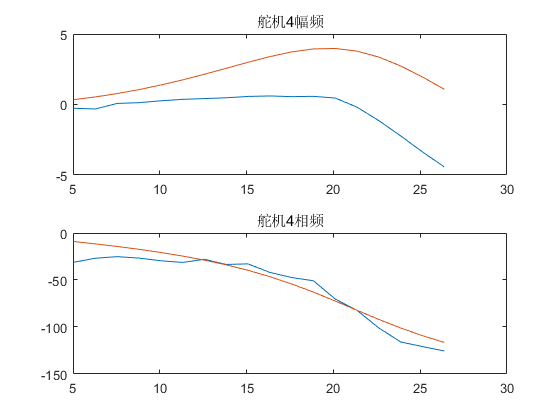

%test1
clear;
close all;
dataA=1:18;
datafz=0.8:0.2:4.2;
Amphidatar=zeros(18,2,4);
Amphidatah=zeros(18,2,4);
for k=1:4
for i=1:18
    file=sprintf('%d.dat',i);
    datar=readdat(file);
%     figure((k-1)*18+i);
    [t,c,d]=preprocess(datar,k,floor(18/i)-1);
    [Am,phi]=analysis(c,d);
    Amphidatar(i,:,k)=[Am,phi];
    Amphidatah(i,:,k)=[20*log10(Am),phi*180/pi];
end
end
sysm=[];
for k=1:4
     ss=datafz*2*pi;
     datas=Amphidatar(1:end,1,k).*exp(Amphidatar(1:end,2,k)*1j);
 
     sys=ident_f1_2(datas,ss*1j);
    % figure(k+4);
   % bode(sys.num,sys.den,ss);
     sysm=[sysm;sys];
end

for k=1:4
    [mag,phase,wout] = bode(sysm(k),ss);
    mag=20*log10(reshape(mag,[18,1]));
    phase=redeg(reshape(phase,[18,1]));
     figure(k);
     subplot(2,1,1);
     plot(ss,Amphidatah(:,1,k));hold on;
     plot(wout,mag);
     title(sprintf('舵机%d幅频',k)); 
      subplot(2,1,2);
     plot(ss,Amphidatah(:,2,k));hold on;
      plot(wout,phase);
     title(sprintf('舵机%d相频',k)); 
end

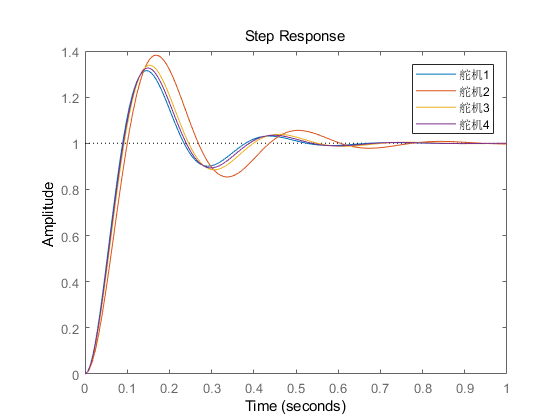



    figure(5);
for k=1:4
    step(sysm(k));hold on
end
legend('舵机1','舵机2','舵机3','舵机4');